# Examples of Planar Distribution Functions

The following script reproduces some of the examples of different mathematical forms used to reconstruct planar orientation distribution functions. from C. L. Tucker, "Planar Fiber Orientation: Jeffery, Non-Orthotropic Closures and Reconstructing Distribution Functions," submitted to the *Journal of Non-Newtonian Fluid Mechanics*, June, 2022.  

The first mathematical form is the Jeffery distribution, also known as the angular central Gaussian,


$$\tilde{\psi}_\phi ( \mathbf{p} ) = \frac{1}{2 \pi} \: \left(\mathbf{p}  \cdot \mathbf{B} ^{-1} \cdot \mathbf{p}  \right)^{-1}$$


where $\mathbf{p}$ is a unit vector giving the fiber orientation and $\mathbf{B}^{-1} = \mathbf{F}^{-T} \cdot \mathbf{F}^{-1}$ is the Piola deformation tensor.  The deformation gradient tensor $\mathbf{F}$ needed to achieve an eigenvalue $\lambda_1$ of the second-order orientation tensor is, in the principal axes of that tensor,


$$\bar{\mathbf{F}} = \left[ \begin{array}{cc}
                    F & 0 \\
                    0 & 1/F
              \end{array} \right]
      \quad \text{with} \quad
      F = \sqrt{\frac{\lambda_1}{1 - \lambda_1}}$$


Second is the ellipse radius (ER) distribution,


$$\tilde{\psi}_\phi ( \mathbf{p}) = \left( \mathbf{p} \cdot \mathbf{T} \cdot  \mathbf{p} \right)^{-1/2r}$$


where $r \equiv b/a$ is the axis ratio of an ellipse and the second-order tensor $\mathbf{T}$ is given in the principal axes of $\mathbf{A}$ by


$$\bar{\mathbf{T}} = Z^{-2r}  \left[ \begin{array}{cc}
                                 r^2 & 0 \\
                                 0   & 1
                               \end{array} \right]$$


The constant $Z$ is adjusted to satisfy normalization.  

Third is the Bingham distribution, which is also the second-order maximum entropy distribution:


$$\tilde{\psi}_\phi (\mathbf{p}) =  \exp \left( \mathbf{p} \cdot \mathbf{T} \cdot \mathbf{p} \right)$$


A fourth option is the fourth-order maximum entropy distribution, ME4:


$$ \tilde{\psi}_\phi (\mathbf{p}) =  \exp \left(\mathbf{p} \mathbf{p} : \mathbb{T}  : \mathbf{p} \mathbf{p} \right)$$


Here $\mathbb{T}$ is a fourth-order, completely symmetric tensor.

The functions `JefferyDistn2D`, `fitERdistn2D`, `fitBingham2D`, and `fitMaxEntropy2D` will match these distributions to given orientation tensor data.  While the Jeffery, ER and Bingham distributions are matched to second-order orientation tensors, the ME4 distribution is matched to a fourth-order orientation tensor.  That information can be the exact value or can come from a closure approximation, so there are multiple versions of ME4. 

Here is the example from the paper.  First we set some parameters.

lambda1  = 0.75; % Eigenvalue of orientation tensor
eta1     = [0, 0.04, -0.04];
eta2     = [0, 0, 0];
npoints  = 180;  % Number of points for dist'ns. 
nplot    = 3;    % Plot every nplot^th symbol for ME4 PDFs
fontsize = 24;
fprintf('Second-order orientation tensor:\n')

Second-order orientation tensor:


A = diag([lambda1, 1-lambda1])

A =     0.7500         0
         0    0.2500


Next, create the distributions based on the second-order orientation tensor, and plot them.

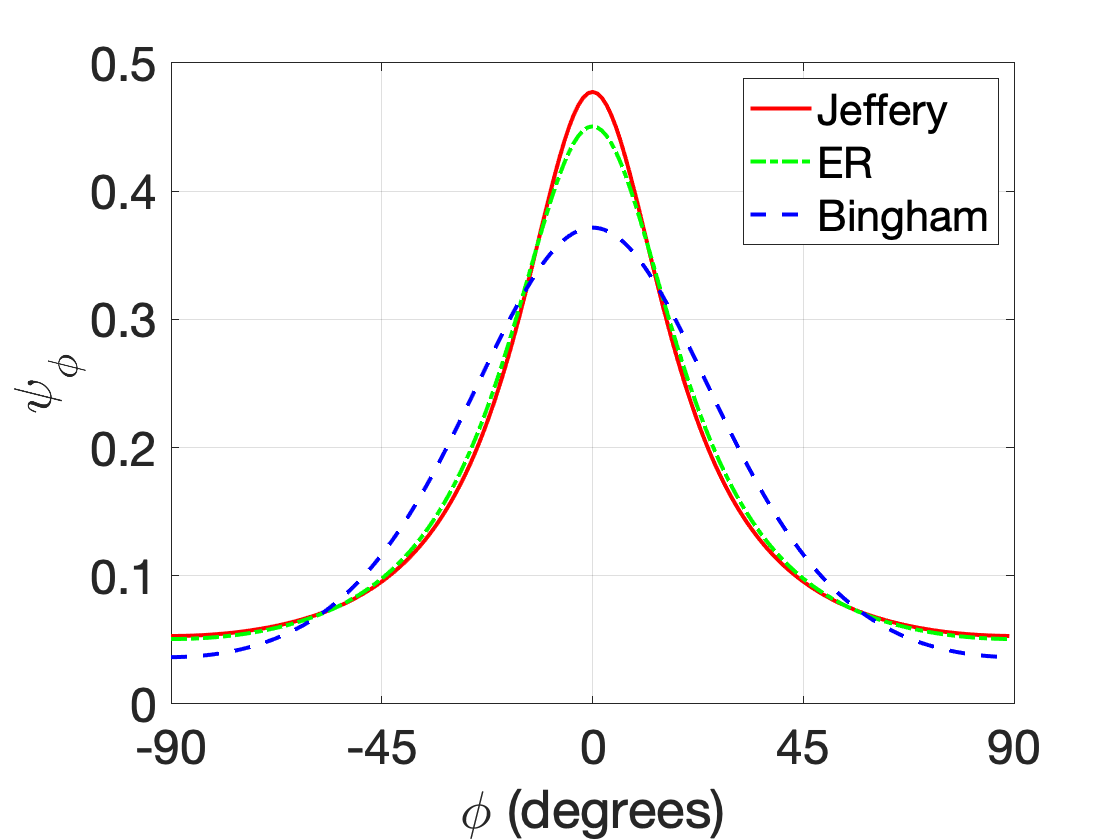

% Jeffery distribution
[psiJ, phiJ, AJ, A4J] = JefferyDistn2D(A, npoints);

% ER distribution
[~, psiE, phiE, AE, A4E] = fitERdistn2D(A, npoints);

% Bingham distribution
[~, psiB, phiB, AB, A4B] = fitBingham2D(A, npoints);

figure(1); clf
plot(rad2deg(phiJ), psiJ, 'r-',  ...
     rad2deg(phiE), psiE, 'g-.', ...
     rad2deg(phiB), psiB, 'b--', ...
     'LineWidth', 2)
set(gca, 'FontSize', fontsize, 'Xtick', -90:45:90)
axval = axis;
axis([-90 90 axval(3:4)])
xlabel('\phi (degrees)')
ylabel('\psi_\phi')
legend('Jeffery', 'ER', 'Bingham')
grid on; box on

The Jeffery distribution has the sharpest peak, the ER distribution is close for this value of $\lambda_1$, and the Bingham distribution is the smoothest.

For the ME4 distribution we select several fourth-order orientation tensors by starting with the natural closure for $\mathbb{A}$, and then adding a deviatoric tensor that is controlled by two parameters, $\eta_1$ and $\eta_2$.  (See the journal article for details).  We'll keep the Jeffery distribution in this plot for comparison.

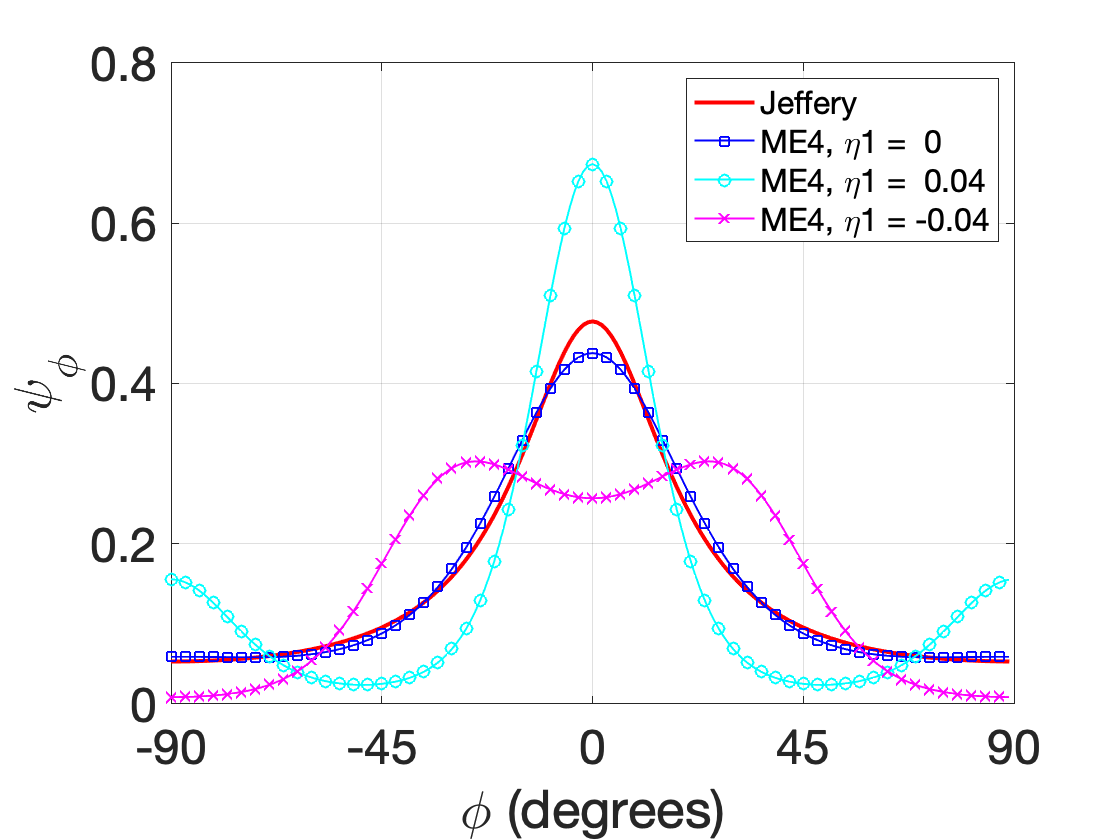

figure(2); clf; hold on
% Plot Jeffery distribution
plot(rad2deg(phiJ), psiJ, 'r-', 'LineWidth', 2)
% Cycle through the eta values
linestyle = {'b-s', 'c-o', 'm-x'};
for i = 1:length(eta1)
    % Fourth-order orientation tensor corresponding to eta1(i)
    A1111 = eta1(i) + (lambda1 + lambda1^2)/2;
    A1122 = lambda1 - A1111;
    A2222 = 1 - A1111 - 2*A1122;
    A1112 = eta2(i);
    A2212 = -A1112;
    A4 = [A1111, A1122, A1112; ...
          A1122, A2222, A2212; ...
          A1112, A2212, A1122];
    % ME4 distribution function for this A4
    [~, psiME4, phi] = fitMaxEntropy2D(A4, npoints);
    % Add this curve to the plot
    plot(rad2deg(phi), psiME4, linestyle{i}, ...
         'LineWidth', 1, ...
         'MarkerIndices', 1:nplot:length(psiME4))
end
set(gca, 'FontSize', fontsize, 'Xtick', -90:45:90)
axval = axis;
axis([-90 90 axval(3:4)])
xlabel('\phi (degrees)')
ylabel('\psi_\phi')
legend('Jeffery', 'ME4, \eta1 =  0', ...
       'ME4, \eta1 =  0.04', 'ME4, \eta1 = -0.04', ...
       'FontSize', 16)
grid on; box on

The ME4 distribution with $\eta_1 = 0$ is close to the Jeffery distribution, but does not exactly match it.  Increasing $\eta_1$ causes the orientation to become more peaked in the main direction, $\phi = 0$, but there is also a secondary peak at $\phi = \pm90^\circ$.  

For $\eta_1 < 0$, the main direction of orientation no longer the highest value of the distribution function.  Instead, there are peaks at $\pm \phi_1$, which is around $30^\circ$ in this case.   